# Specify the Order of Table Columns

To specify the order of table columns, add an `mlreportgen.ppt.FlowDirection` format object to the S`tyle` property of an `mlreportgen.ppt.Table` object. This example specifies a right-to-left column order.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myFlowDirection.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Content");

Create a table and specify the column flow direction.

t = Table({'entry(1,1)', 'entry(1,2)'; 'entry(2,1)', 'entry(2,2)'});
t.Style = [t.Style {FlowDirection("RightToLeft")}];

Add the table to the slide.

replace(slide,"Content",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

In the generated table, the second column appears first.

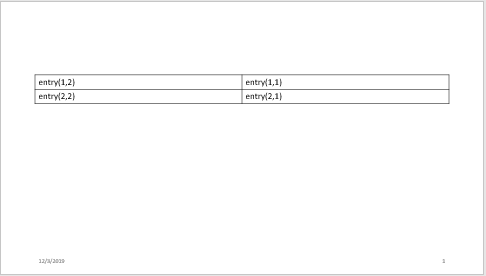

*Copyright 2019 The MathWorks, Inc.*